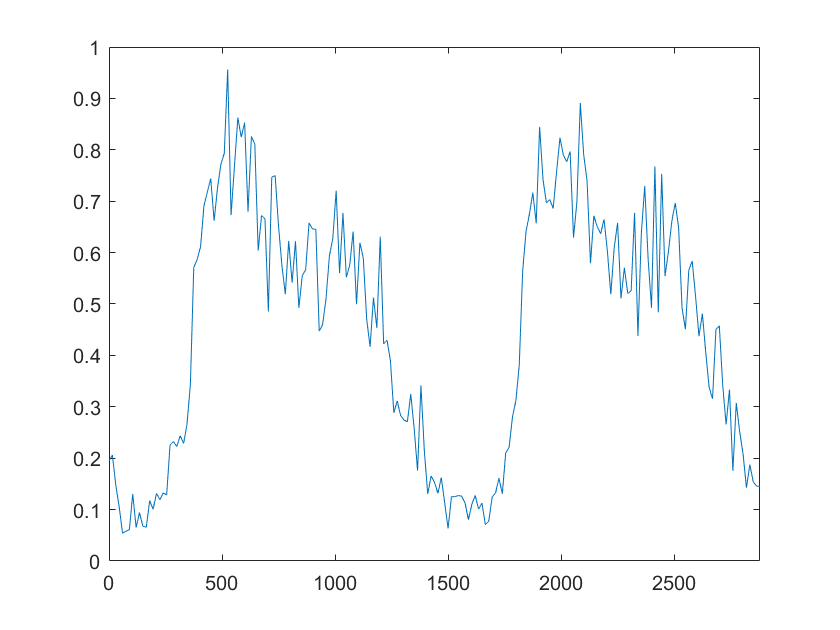

clear all; close all;
load('resampdataset.mat')
%Sampling-time is 1/15min, meaning that time-axis is in minutes
oneday = 60*24; %one day in minutes
n = 2; % How many days do we wants to see?
% figure(1)
% subplot(2,1,1)
% plot(time,q_u1)
% xlim([0 n*oneday])
% subplot(2,1,2)
plot(time,q_u2/max(q_u2))
xlim([0 n*oneday])

## FFT

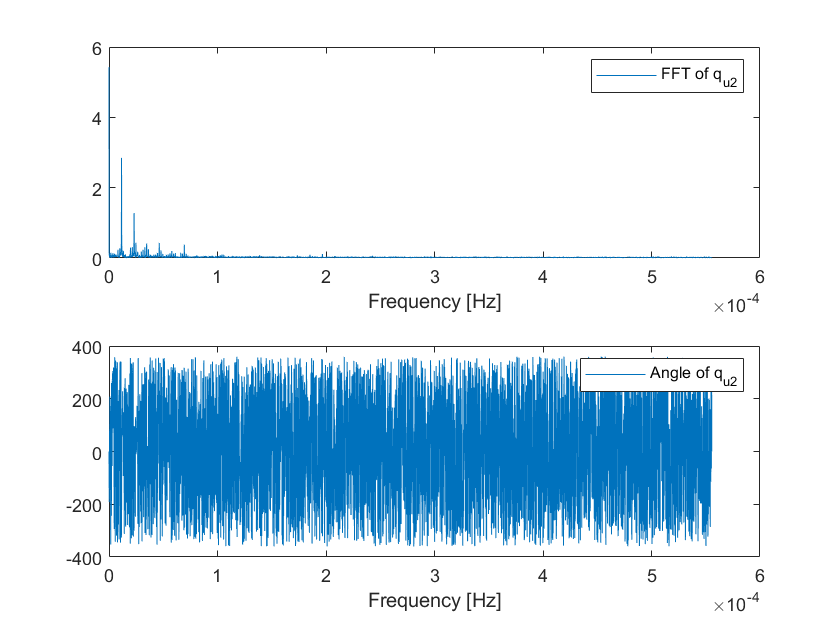

%FFT of q_u1
% y1 = fft(q_u1);
% P2 = abs(y1/length(q_u1));
% P1 = P2(1:length(q_u1)/2+1);
% P1(2:end-1) = 2*P1(2:end-1);

y11 = fft(q_u2);
P22 = abs(y11/length(q_u2));
P11 = P22(1:length(q_u2)/2+1);
P11(2:end-1) = 2*P11(2:end-1);

P22a = angle(y11/length(q_u2));
P11a = P22a(1:length(q_u2)/2+1);
P11a(2:end-1) = 2*P11a(2:end-1);

%Time-axis
f = 1/(15*60)*(0:(length(q_u1)/2))/length(q_u1);
%Subplots with FFT of q_u1 & q_u2
figure()
subplot(2,1,1) 
plot(f,P11)
legend('FFT of q_{u2}')
xlabel('Frequency [Hz]')
subplot(2,1,2)
plot(f,rad2deg(P11a))
legend('Angle of q_{u2}')
xlabel('Frequency [Hz]')

## Create waves and shit

%Periode of harmonics in min:
T1 = 1/(1.15495*10^-5 * 60); 
T2 = 1/(2.30989*10^-5 * 60);
T3 = 1/(3.46484*10^-5 * 60);
T4 = 1/(4.63291*10^-5 * 60);

%Identify DC + 4 harmonic components:
K = 5.4274;
h1 = 2.84716;
h2 = 1.2767;
h3 = 0.411351;
h4 = 0.428664;
tot = K + h1+h2+h3+h4;

% %Phaseshift of the harmonics:
% for ii = 1:length(P11a)
%    if P11(ii) > 0.411
%        ii
%    end
% end

ph1 = P11a(89)

ph1 = -5.2790

ph2 = P11a(177)

ph2 = -5.0431

ph3 = P11a(265)

ph3 = 5.2835

ph4 = P11a(354)

ph4 = -2.0002

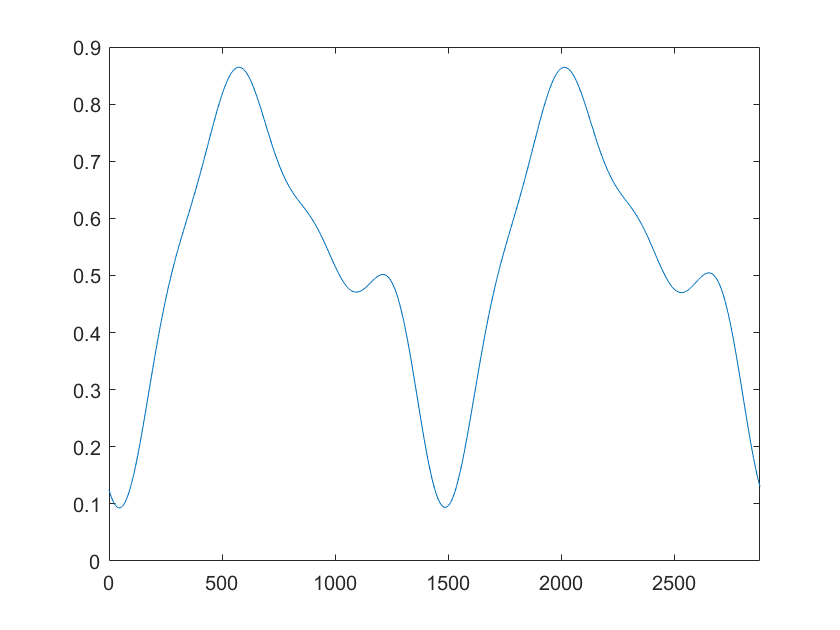


theta1 = ph1*2*pi*1/(T1/60);
theta2 = ph2*2*pi*1/(T2/60);
theta3 = ph3*2*pi*1/(T3/60);
theta4 = ph4*2*pi*1/(T4/60);

t = 0:1:60*48;
% (K+firsth+sech+thirdh+fourthh)/tot;
w1 = h1/tot * sin(2*pi*1/T1 * t + theta1);
w2 = h2/tot * sin(2*pi*1/T2 * t + theta2);
w3 = h3/tot * sin(2*pi*1/T3 * t + theta3);
w4 = h4/tot * sin(2*pi*1/T4 * t + theta4);

ConsumerPattern = (K/tot)+w1+w2+w3+w4;
figure()
plot(t,ConsumerPattern)
xlim([0 2*24*60])

## Comparisson of data set and harmonic (DC + 4)

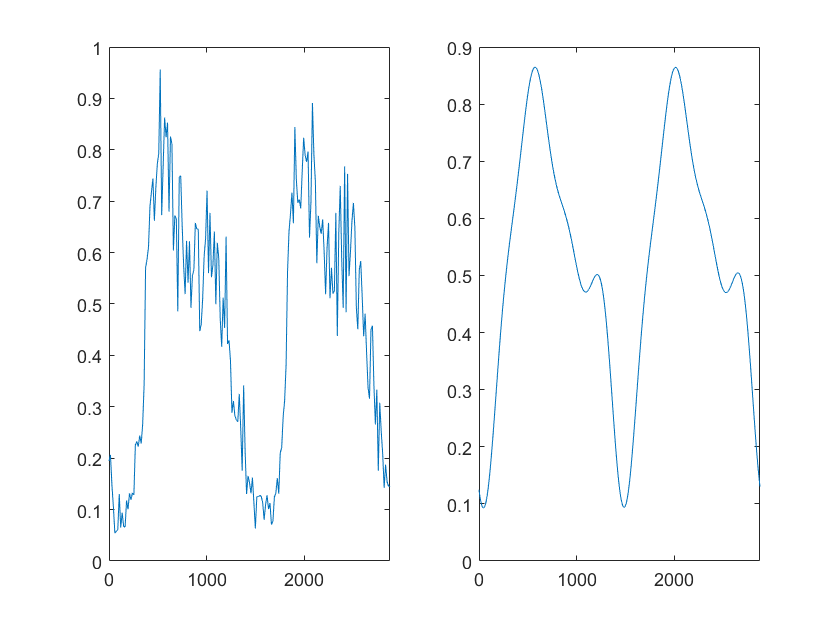

figure()
subplot(1,2,1)
plot(time,q_u2/max(q_u2))
xlim([0 2*oneday])
subplot(1,2,2)
plot(t,ConsumerPattern)
xlim([0 60*48])

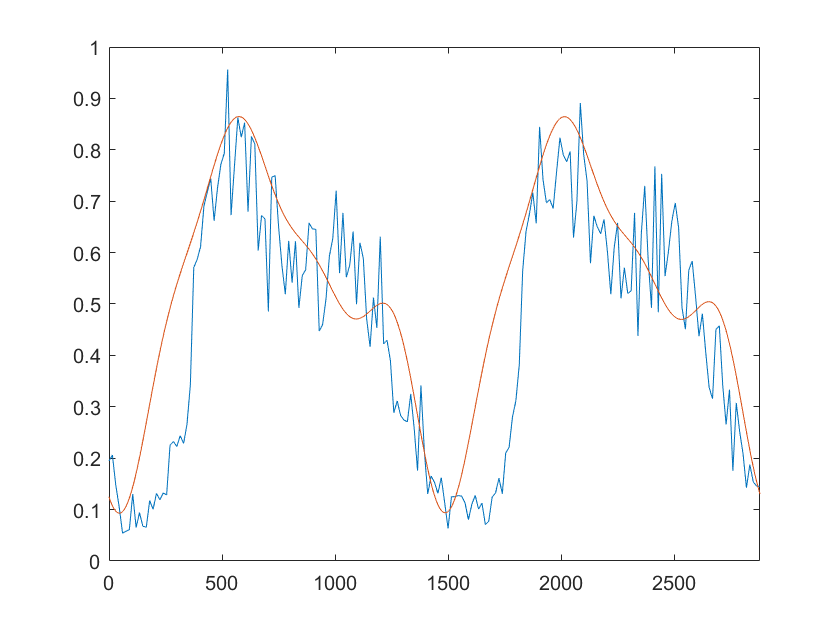


figure()
plot(time,q_u2/max(q_u2))
hold on
plot(t,ConsumerPattern)
hold off
xlim([0 60*48])

## Y = C*x

% clear t; 
% w1 =@(t) h1/tot * cos(2*pi*1/T1 * t + theta*2*pi*1/(T1/60)-pi/2);
% w2 =@(t) h2/tot * cos(2*pi*1/T2 * t + theta*2*pi*1/(T2/60)-pi/2);
% w3 =@(t) h3/tot * cos(2*pi*1/T3 * t + theta*2*pi*1/(T3/60)-pi/2);
% w4 =@(t) h4/tot * cos(2*pi*1/T4 * t + theta*2*pi*1/(T4/60)-pi/2);
% 
% c = [1 1 0 1 0 1 0 1 0];
% x =@(t) [K/tot w1(t) 0 w2(t) 0 w3(t) 0 w4(t) 0]';
% 
% for t=1:1:60*48
%     y(t) = c*x(t);
% end

## Comparisson of the Harminic model and ss model

% figure()
% plot(ConsumerPattern)
% hold on 
% plot(y,'--')
% hold off